# Tutorial for ITS project

This document provides example code to help with the group project on the ITS system.

## Overview

The first step is to load the road network graph into the memory

  graph with properties:

    Edges: [15959×5 table]
    Nodes: [14844×3 table]



ans =              Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'Name'  'Lat'  'Long'}
    VariableDescriptions: {}
           VariableUnits: {}
                RowNames: {}


ans =              Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'EndNodes'  'Weight'  'Name'  'Distance'  'Speed'}
    VariableDescriptions: {}
           VariableUnits: {}
                RowNames: {}


ans =         Name         Lat       Long  
    ____________    ______    _______

    'I-80@+X121'    41.056    -75.723


ans =     'I-80@+X121'


node_id = 1

ans =     'I-80@+X121'


ans =              EndNodes             Weight     Name     Distance    Speed
    __________________________    ______    ______    ________    _____

    'I-80@+X121'    'I-80@277'    1.3329    'I-80'    1.3329      65   


ans = 65

edge_id = 1

ans =              EndNodes             Weight     Name     Distance    Speed
    __________________________    ______    ______    ________    _____

    'I-80@+X121'    'I-80@277'    1.3329    'I-80'    1.3329      65   


Trip 1 : From [US219@SpeRd] to [PA147/US22/US322]


Trip 2 : From [I-77@114] to [US219@+X10|PA]


Trip 3 : From [US40@MD7/155] to [US52Ken@US119_N&US119@US52_N]


Trip 4 : From [US15@HesRd] to [I-84(20)/PA507]


Trip 5 : From [I-40(274)/NC751] to [US15_S/US33_E]


Trip  1 - 198.54 miles, travel time = 224.24 mins, average speed =  54.04


Trip  2 - 219.22 miles, travel time = 208.85 mins, average speed =  62.13


Trip  3 - 452.43 miles, travel time = 454.76 mins, average speed =  59.57


Trip  4 - 518.57 miles, travel time = 486.10 mins, average speed =  63.87


Trip  5 - 222.76 miles, travel time = 211.02 mins, average speed =  63.11


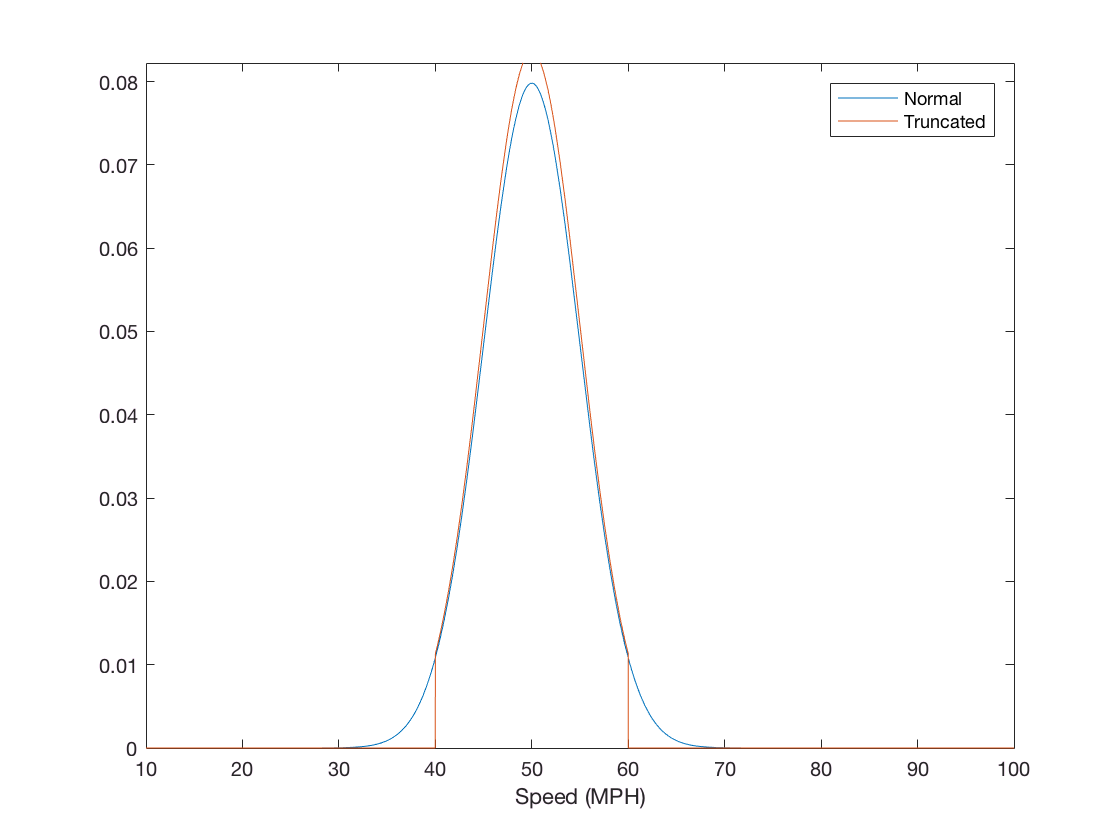

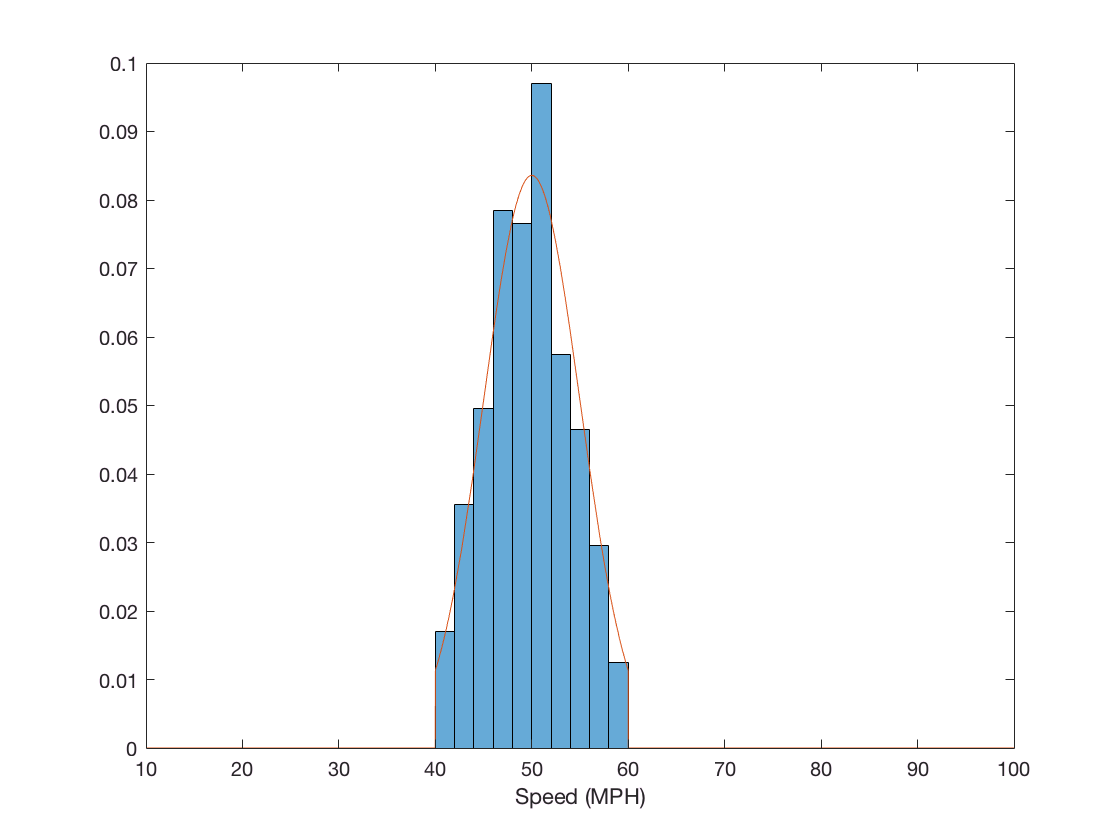

% Load the data file.
load EastCoast

%  Assume the graph is in the variable G.

Next we are going to explore the graph data structure.

disp(G)

We can see from the output of the display command that the graph is made up of two tables: Edges and Nodes. We will examine the node table first. 

% The command below will list the variables (columns) in the table.
G.Nodes.Properties

Examining the properties reveals there are three columns in the table:  Name, Lat (Latitude), and Long (Longitude).  Next we can examine the properties of the Edges table.

% The command below will list the variables (columns)
% in the table.
G.Edges.Properties

The Edges table has five columns: EndNodes (Names of the nodes at either side of the edge), Weight (Value used when computing the path length in the graph), Distance (The length of the edge in miles), and Speed (nominal speed along the edge). Note,  EndNodes is a cell array with two elements.

We can access a node  by its position in the table

G.Nodes(1,:)

or a speicific variable of the table.

G.Nodes.Name(1)

We can also lookup the ID (row) of the table from the node name using 

node_id = findnode(G,'I-80@+X121')
G.Nodes.Name(node_id)

Edges can also be accessed in a similar manner.

G.Edges(1,:)

or

G.Edges.Speed(1)

If we know the names of the two ends of the edge we can find the index of the edge.

edge_id = findedge(G, 'I-80@277', 'I-80@+X121')
G.Edges(edge_id,:)

## Computing times through the graph

The ITS problem requires computing travel times through the road network (graph).  The code below will compute the travel times for five random trips through the baseline graph.

% Define unit conversion
mins_per_hr = 60;

First, randomly select five trips. The command randi(k,n,m) will generate a n x m matrix of random integers between 1 and k.

% Select start and stop points for tests
% Randomly selects 5 trips
trips = randi(numnodes(G),5,2); % numnodes(G) returns the # of nodes in the graph
for k=1:size(trips,1) % size(trips,1) returns the number of rows in the matrix
    % Get the names of the start and end points
    start_name = G.Nodes.Name(trips(k,1)); % Returns a cell array
    end_name   = G.Nodes.Name(trips(k,2)); % Returns a cell array
    fprintf('Trip %d : From [%s] to [%s]\n', ...
        k, start_name{1}, end_name{1});
end

We need to set the weights in the graph to the travel time.  We can use vectorization to perform the operation quickly.

% Change the graph weights to equal the travel time
% Note the use of vectorization to speed up the computation
G.Edges.Weight = G.Edges.Distance ./ G.Edges.Speed * mins_per_hr;

Next, we are going to loop over each of the trips and find the shortest path through the graph based on the travel time.

% Evaluate the trips using the baseline graph
for k=1:size(trips,1)  
    % Find the shortest path from start to end. Indicate all the 
    % Weights are positive to support a faster algorithm
    [path_nominal , t_nominal] = shortestpath(G,trips(k,1),trips(k,2),...
         'method','positive'); 
     
    % Get all the node IDs (numbers) for each node in the path
    node_ids = findnode(G,path_nominal);
    % Get all the edge IDs (numbers) for each edge in the path
    edge_ids = findedge(G, node_ids(1:end-1), node_ids(2:end));
    % Compute the distance of the path by summing the length of each edge
    nominal_distance = sum(G.Edges.Distance( edge_ids ) );
    % Compute the average speed along the path
    average_speed = mean(G.Edges.Speed( edge_ids ) );
    
    fprintf('Trip %2d - %6.2f miles, travel time = %6.2f mins, average speed = %6.2f\n', ...
        k, nominal_distance, t_nominal, average_speed);
end

## Generating Random Speeds

The problem calls for generating random speeds.  Assume we know the speeds are Normally distributed with a mean of 50 mph and a standard deviation of 5 mph.  We can create a distribution that generates the specific random variable using the command below. **Note, each team will need to determine the speed distributions using the provided data.**

pd = makedist('Normal',50,5);

One of the challenges with using a normal distribution is the range of the values is from negative infinity to positive infinity. Since we can't have negative or infinite speeds we needs to truncate the distribution. Matlab provides the a command to truncate the distribution. The command below will limit the distribution between 30 mph and 80 mph.

pd_trunc  = truncate(pd,40, 60);

Next, we can plot the distribution using the Matlab command fplot.

fplot(@(x) pdf(pd,x),[10 100]);
hold on
fplot(@(x) pdf(pd_trunc,x),[10 100]);
xlabel('Speed (MPH)')
hold off
legend('Normal','Truncated')

Notice the distribution has been truncated and adjusted to ensure the integral is one. We can generate random numbers from this distribution using the MATLAB command below. We will generate 1000 numbers and plot the histogram.

data = random(pd_trunc,[1000,1]);
histogram(data,'Normalization','pdf')
hold on
fplot(@(x) pdf(pd_trunc,x),[10 100]);
xlabel('Speed (MPH)')
hold off

